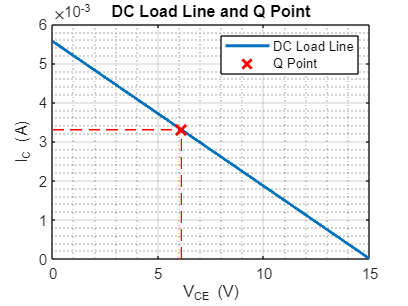

% Parameters
IC_sat = 5.56*10^-3;  
VCE_off = 15;   

% Measured values 
IC_Q = 3.30*10^-3;    
VCE_Q = 6.09;       

% Plot the DC load line
VCE = linspace(0, VCE_off, 1000);
IC = IC_sat - (IC_sat / VCE_off) * VCE;

figure;
ylim([0, IC_sat * 1.5]);

plot(VCE, IC, 'LineWidth', 2);

hold on;

% Plot the Q point with a cross marker
plot(VCE_Q, IC_Q, 'rx', 'MarkerSize', 10, 'LineWidth', 2);

% Add trace lines from the Q point to the respective x and y-axis points
plot([VCE_Q, VCE_Q], [0, IC_Q], 'r--', 'LineWidth', 1);
plot([0, VCE_Q], [IC_Q, IC_Q], 'r--', 'LineWidth', 1);
% xlim([0, VCE_off * 0.5]);
hold off;


% Customize the plot
title('DC Load Line and Q Point');
xlabel('V_{CE} (V)');
ylabel('I_{C} (A)');
legend('DC Load Line', 'Q Point');
grid on;
grid minor;